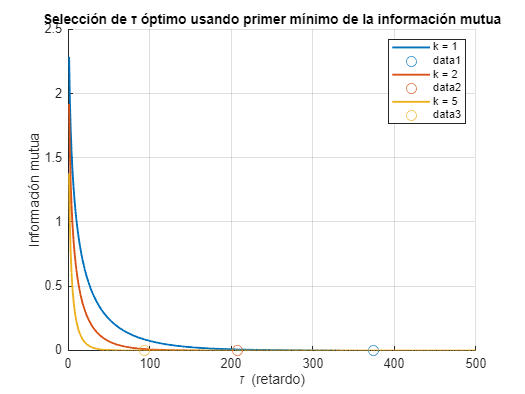

k_values = [1, 2, 5];
colores = lines(length(k_values));
max_tau = 500;
n_bins = 32; % Número de bins para discretización
eta = 1;
T1 = 1;
T2 = 2;
tspan = [0, 100000];
dt = 0.01;
N = tspan(2) / dt;
t = linspace(tspan(1), tspan(2), N);
kb = 1;
x1_0 = 0;
x2_0 = 0;
x1_eq = 0;
x2_eq = 0;

figure;
hold on;
for idx = 1:length(k_values)
    k = k_values(idx);

    x1 = zeros(1, N);
    x2 = zeros(1, N);
    x1(1) = x1_0;
    x2(1) = x2_0;

    sqrt_term1 = sqrt((2 * kb * T1) / eta);
    sqrt_term2 = sqrt((2 * kb * T2) / eta);

    for n = 1:N-1
        dW1 = sqrt(dt) * randn;
        dW2 = sqrt(dt) * randn;
        x1(n+1) = x1(n) + (- 2*k * (x1(n)-x1_eq) + k*(x2(n)-x2_eq))/eta * dt + sqrt_term1/eta * dW1;
        x2(n+1) = x2(n) + (- 2*k *(x2(n)-x2_eq) + k*(x1(n)-x1_eq))/eta * dt + sqrt_term2/eta * dW2;
    end

    % Cálculo de la información mutua
    [tau_opt, mi_values, valid_taus] = optimal_tau_mutual_informationk(x1, max_tau, n_bins);
    plot(valid_taus, mi_values, 'LineWidth', 1.5, 'Color', colores(idx,:), ...
        'DisplayName', ['k = ' num2str(k)]);
    plot(tau_opt, mi_values(valid_taus == tau_opt), 'o', 'Color', colores(idx,:), 'MarkerSize', 8);
end

xlabel('\tau (retardo)');
ylabel('Información mutua');
title('Selección de τ óptimo usando primer mínimo de la información mutua');
legend;
grid on;
hold off;



function [tau_opt, mutual_info, valid_taus] = optimal_tau_mutual_informationk(x, max_tau, n_bins)

    x = (x - min(x)) / (max(x) - min(x));  % Normalización
    mutual_info = NaN(1, max_tau);

    for tau = 1:max_tau
        x_t = x(1:end - tau);
        x_tau = x(1 + tau:end);
        if length(x_t) < 2 || length(x_tau) < 2, continue; end

        [counts, ~, ~] = histcounts2(x_t, x_tau, n_bins, 'Normalization', 'probability');
        p_joint = counts;

        p_x = sum(p_joint, 2);
        p_y = sum(p_joint, 1);

        epsilon = 1e-12;
        p_joint(p_joint == 0) = epsilon;
        p_x(p_x == 0) = epsilon;
        p_y(p_y == 0) = epsilon;

        p_x = p_x(:);
        p_y = p_y(:)';

        p_prod = p_x * p_y;
        mutual_info(tau) = sum(p_joint(:) .* log2(p_joint(:) ./ p_prod(:)));
    end

    valid_taus = find(~isnan(mutual_info));
    mi_values = mutual_info(valid_taus);
    tau_candidates = valid_taus;

    tau_opt = tau_candidates(1);
    for i = 2:length(mi_values)-1
        if mi_values(i) < mi_values(i-1) && mi_values(i) < mi_values(i+1)
            tau_opt = tau_candidates(i);
            break;
        end
    end
    if isempty(tau_opt)
        [~, idx_min] = min(mi_values);
        tau_opt = tau_candidates(idx_min);
    end
end

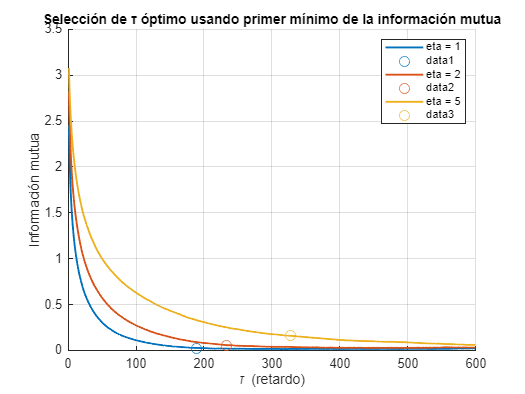

n_values = [1, 2, 5];
colores = lines(length(n_values));
max_tau = 600;
n_bins = 32; % Número de bins para discretización
k = 1;
T1 = 1;
T2 = 3;
tspan = [0, 1000];
dt = 0.01;
N = tspan(2) / dt;
t = linspace(tspan(1), tspan(2), N);
kb = 1;
x1_0 = 0;
x2_0 = 0;
x1_eq = 0;
x2_eq = 0;

figure;
hold on;
for idx = 1:length(n_values)
    eta = n_values(idx);

    x1 = zeros(1, N);
    x2 = zeros(1, N);
    x1(1) = x1_0;
    x2(1) = x2_0;

    sqrt_term1 = sqrt((2 * kb * T1) / eta);
    sqrt_term2 = sqrt((2 * kb * T2) / eta);

    for n = 1:N-1
        dW1 = sqrt(dt) * randn;
        dW2 = sqrt(dt) * randn;
        x1(n+1) = x1(n) + (- 2*k * (x1(n)-x1_eq) + k*(x2(n)-x2_eq))/eta * dt + sqrt_term1/eta * dW1;
        x2(n+1) = x2(n) + (- 2*k *(x2(n)-x2_eq) + k*(x1(n)-x1_eq))/eta * dt + sqrt_term2/eta * dW2;
    end

    % Cálculo de la información mutua
    [tau_opt, mi_values, valid_taus] = optimal_tau_mutual_information(x1, max_tau, n_bins);
    plot(valid_taus, mi_values, 'LineWidth', 1.5, 'Color', colores(idx,:), ...
        'DisplayName', ['eta = ' num2str(eta)]);
    plot(tau_opt, mi_values(valid_taus == tau_opt), 'o', 'Color', colores(idx,:), 'MarkerSize', 8);
end


xlabel('\tau (retardo)');
ylabel('Información mutua');
title('Selección de τ óptimo usando primer mínimo de la información mutua');
legend;
grid on;
hold off;



function [tau_opt, mutual_info, valid_taus] = optimal_tau_mutual_information(x, max_tau, n_bins)

    x = (x - min(x)) / (max(x) - min(x));  % Normalización
    mutual_info = NaN(1, max_tau);

    for tau = 1:max_tau
        x_t = x(1:end - tau);
        x_tau = x(1 + tau:end);
        if length(x_t) < 2 || length(x_tau) < 2, continue; end

        [counts, ~, ~] = histcounts2(x_t, x_tau, n_bins, 'Normalization', 'probability');
        p_joint = counts;

        p_x = sum(p_joint, 2);
        p_y = sum(p_joint, 1);

        epsilon = 1e-12;
        p_joint(p_joint == 0) = epsilon;
        p_x(p_x == 0) = epsilon;
        p_y(p_y == 0) = epsilon;

        p_x = p_x(:);
        p_y = p_y(:)';

        p_prod = p_x * p_y;
        mutual_info(tau) = sum(p_joint(:) .* log2(p_joint(:) ./ p_prod(:)));
    end

    valid_taus = find(~isnan(mutual_info));
    mi_values = mutual_info(valid_taus);
    tau_candidates = valid_taus;

    tau_opt = tau_candidates(1);
    for i = 2:length(mi_values)-1
        if mi_values(i) < mi_values(i-1) && mi_values(i) < mi_values(i+1)
            tau_opt = tau_candidates(i);
            break;
        end
    end
    if isempty(tau_opt)
        [~, idx_min] = min(mi_values);
        tau_opt = tau_candidates(idx_min);
    end
end